HPB_st.name='HPB'; 
HPB_st.lat=47.8015;
HPB_st.lon=11.0096;
HPB_st.alt=985;
HPB_st.env='Mt';
HPB_st.footp='RB';


HPB_rd=read_betsy('hpb_2004_2017',HPB_st.name);

datevec(HPB_rd.Time(1))

ans =         2004           1           2           0           0           0


datevec(HPB_rd.Time(end))

ans =         2018           1           1           0           0           0


prctile(HPB_rd.U_S11,[5 50 95])

ans =     9.5000   23.4250   43.9000


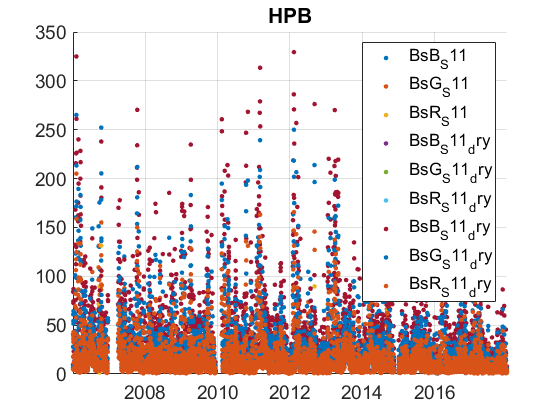

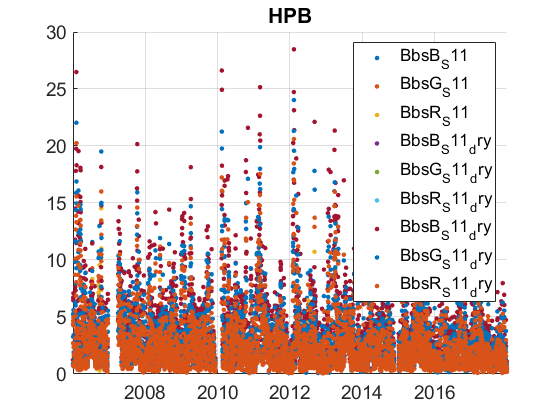

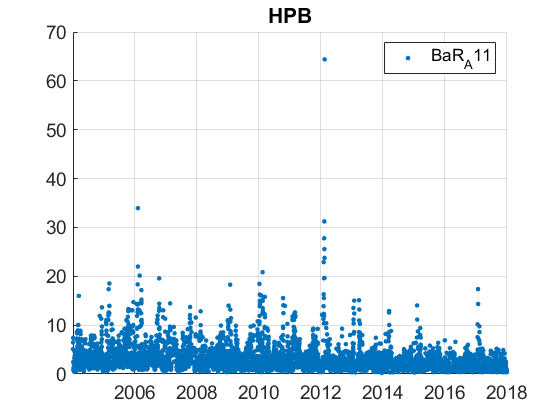

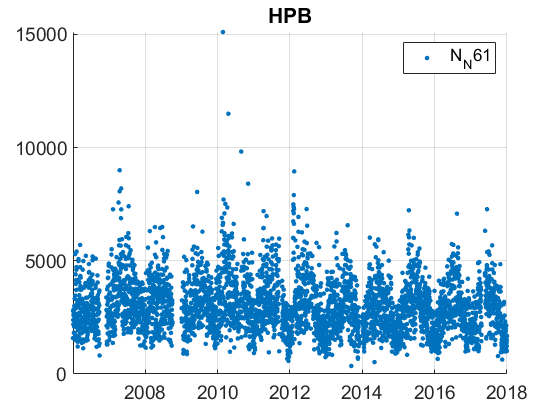

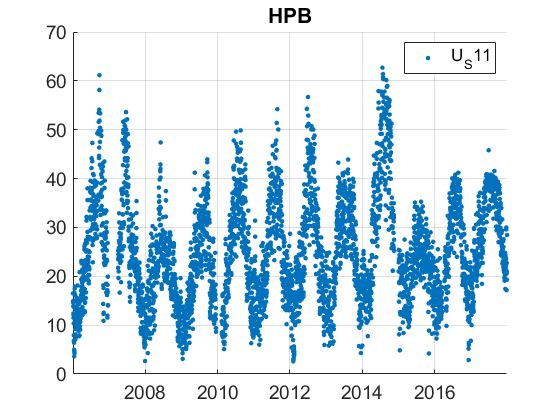

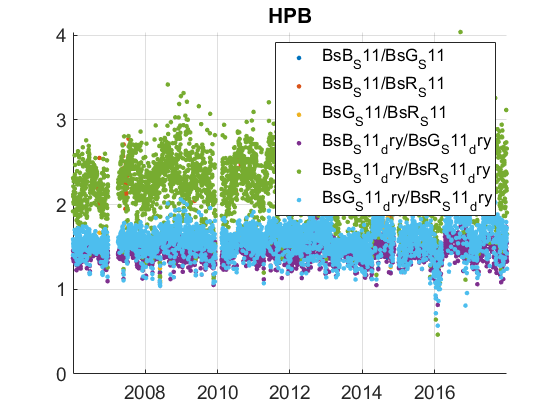

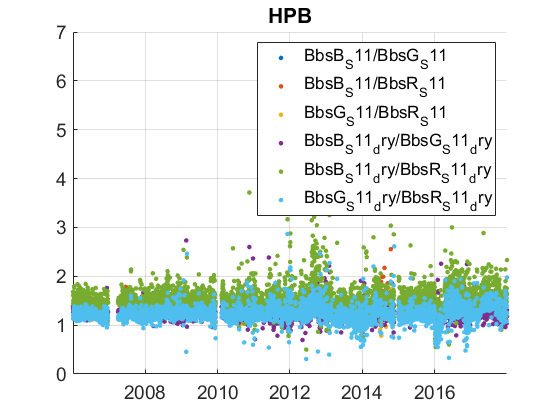

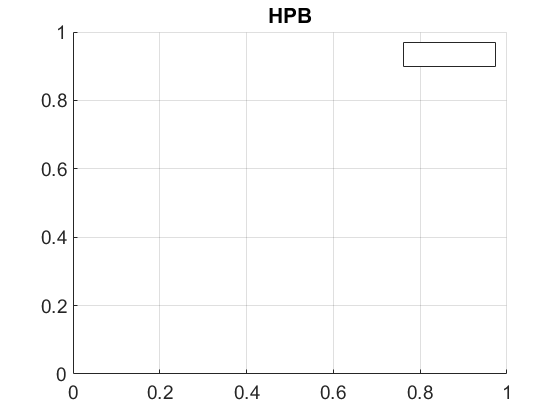

plotFigControl(HPB_rd,HPB_st.name);

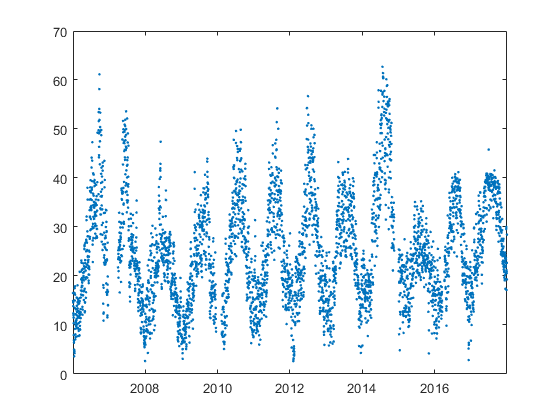

% 1 size cut, ok
% sc: ok,  no negatives, not so clear seasonlity, somewhat higher in winter
% abs: 2 size cut, max in summer, no negatives
% figure
% plot(HPB_rd.Time,HPB_rd.U_S11,'.');

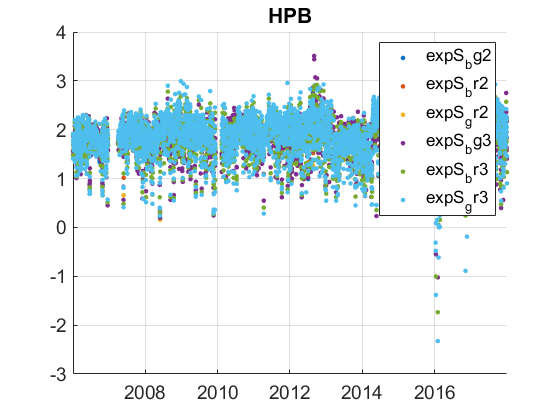

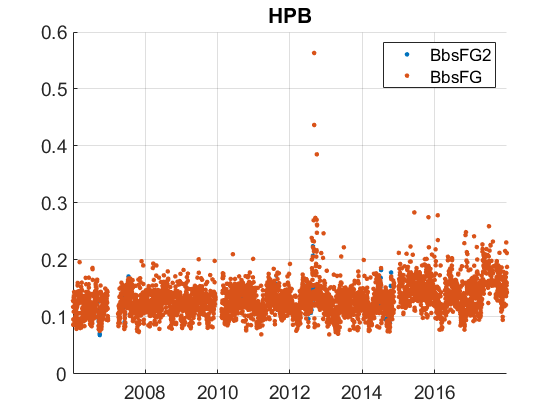

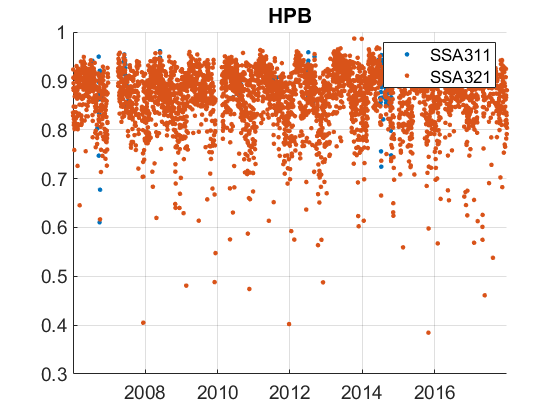

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
HPB_cal=compute_exp_SSA(HPB_rd,lambdaSC, lambdaAE);
plotFigControl_cal(HPB_cal,HPB_st.name);

%Questions:
%problems:

%humidity: there is large variation in max humidity with much lower values since 2015 (2013): is there any change in the dryer ?

% scat+ backscat: it seems that there is a kind of rupture in end 2014/2015 with lower values thereafter. Any idea?
% scat exponent: there is several issues concerning all pair-wise exponents (see figure) with break points in February 2009, April 2018 and April 2016. Do you have explanations ?
%backscattering fraction: it seems to have a kind of rupture in April 2012, January 2015 and April 2017. Should the high values in September be deleted?

%abs MAAP: are the high values in February 2012 real ? should be deleted ?

%N: there is also something strange (very high values) in February 2012:

HPB_tr=HPB_rd;
HPB_tr.y=year(HPB_tr.Time);
% begin at the beginning of a year: 2004 for absorption
%end 2017
P=timerange('2004-01-01','2018-01-01');
HPB_tr=HPB_tr(P,:);

% PM1: 2012-2015: too short, not to analyse
%abs: use AE31 also only until end of 2015.
names=fieldnames(HPB_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_";"N";"Uu";"U1"]) ;
N=names(c);
for i=1:length(N)
    HPB_tr.(N{i})=[];
end

%begin 2006 for scattering: already NAN
%trend in RH and dry to compute
%abs: ok
% probably not much change for exp and BbsF dry: forget
HPB_tr.BsB_S11_dry=[];
HPB_tr.BsR_S11_dry=[];
HPB_tr.BbsB_S11_dry=[];
HPB_tr.BbsR_S11_dry=[];

% not same wavelength, abs should be corrected for SSA trend

HPB_cal2=compute_exp_SSA(HPB_tr,lambdaSC, lambdaAE);
HPB_cal2.SSA=HPB_tr.BsG_S11./(HPB_tr.BsG_S11+HPB_tr.BaR_A11.*(637/550));
HPB_cal2.BbsFG=HPB_tr.BbsG_S11./HPB_tr.BsG_S11;
HPB_cal2.expS_bg=real(-log(HPB_tr.BsB_S11./HPB_tr.BsG_S11)/log(lambdaSC(1)/lambdaSC(2)));
HPB_cal2.expS_bg3=[];
HPB_cal2.expS_br3=[];
HPB_cal2.expS_gr3=[];
HPB_cal2.SSA311=[];
HPB_cal2.SSA321=[];
HPB_cal2.BbsFG2=[];
HPB_tr=outerjoin(HPB_tr, HPB_cal2);

%do not compute trend on scat and backscat b/r
HPB_tr.BsB_S11=[];
HPB_tr.BsR_S11=[];
HPB_tr.BbsB_S11=[];
HPB_tr.BbsR_S11=[];

%exp: use bg,not sure that it is homogeneous
%BbsF: probably wrong increasing trend due to instrumental problem.

HPB_result= all_trend_STN(HPB_tr,HPB_st); 

%there is rupture in BbsF and in expS: not considered
HPB_result_D=HPB_result;
s=startsWith( HPB_result_D.parameter,["expS";"BbsF"]);
HPB_result_D=HPB_result_D(~s,:);